## Please, Edit file name

%fn = 'D:\SPMDATAActive\Z-Spectroscopy00004.dat' %파일이름
%fn = 'D:\SPMDATAActive\Z-Spectroscopy00007.dat' %파일이름
fn = 'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00003.dat'

fn = 'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00003.dat'

xcutP = 0.14% Elbow값

xcutP = 0.1400

## Do not Touch here

load

[header, data, channels] = loaddat(fn);

Determine Elbow

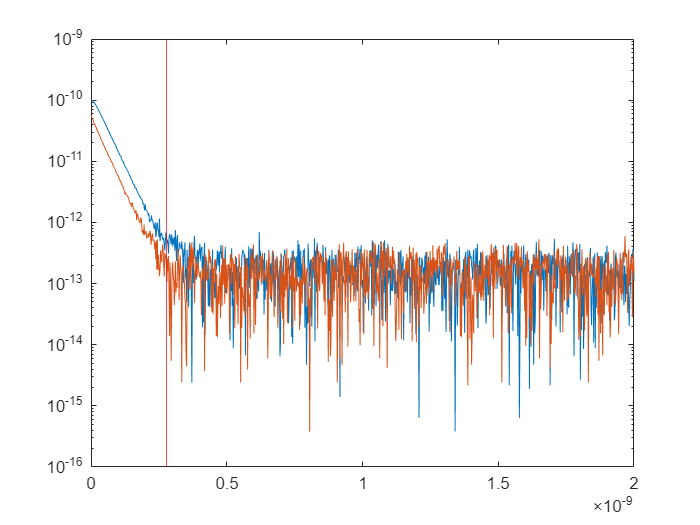

x = data(:,1);
y = abs(data(:,2));
plot(x,y);
hold on
plot(x,abs(data(:,3)));
hold off
yscale log;

xcut = quantile(x,xcutP );
xline(xcut,'r');

[~,argXcut] = min(abs((x-xcut)));

Linear Fitting

xEff = x(1:argXcut);
lyEff = log(y(1:argXcut));
plot(xEff,lyEff);
result = fitlm(xEff,lyEff)

result = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)        -22.895      0.020803    -1100.5    5.3245e-281
    x1             -2.0559e+10    1.2866e+08    -159.79    3.6481e-162


관측값 개수: 144, 오차 자유도: 142
RMS 오차: 0.125
결정계수: 0.994, 수정된 결정계수: 0.994
상수 모델에 대한 F-통계량: 2.55e+04, p-값 = 3.65e-162

pred = result.predict(xEff)

pred =   -22.8945
  -22.9347
  -22.9749
  -23.0151
  -23.0553
  -23.0955
  -23.1357
  -23.1759
  -23.2161
  -23.2563


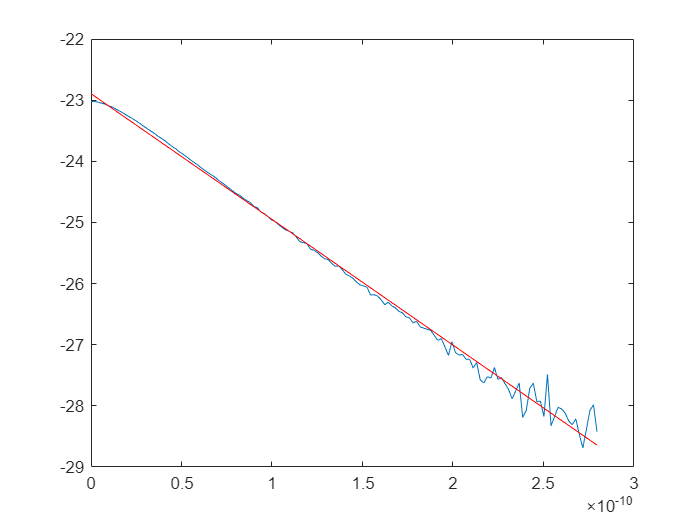

hold on
plot(xEff,pred,'r')
hold off

determine work function

me = 9.1093837*10^(-31) % Electron Mass (kg)

me = 9.1094e-31

hbar = 1.054571817*10^(-34) % Planck Constant (J/s)

hbar = 1.0546e-34

a = result.Coefficients.Estimate(2)

a = -2.0559e+10

qe = 1.60217663 * 10^(-19)

qe = 1.6022e-19

phiV = ((a*hbar)^2)/(8*me)

phiV = 6.4503e-19

phieV = phiV/qe

phieV = 4.0259


goodness = result.Rsquared.Ordinary

phieV = 3.2940

function [header, data, channels] = loaddat(fn)

goodness = 0.9975

% loaddat  Nanonis DAT ASCII file loader
%   [header, data, channels] = loaddat(fn) reads a Nanonis 
%   DAT ASCII file fn.
%   fn: path of the .dat file to read.
%   header: header info of the data file.
%   data: contains the data of all channels, each column in the
%       data array corresponds to an acquired channel.
%   channels: contains the names of the data channels.

data=''; header=''; channels='';

if exist(fn, 'file')
    fid = fopen(fn, 'r', 'ieee-be');    % open with big-endian
else
    fprintf('File does not exist.\n');
    return;
end

% read header data
% The header consists of key-value pairs, separated by a tab character
% e.g. Settling time (s)	200E-6	
% The beginning of the data block starts with [DATA]
while 1
    s = strtrim(fgetl(fid));
    if strcmp(upper(s),'[DATA]')
        break
    end
    
    %s1 = strsplit(s,char(9));  % not defined in older Matlab versions
    s1 = strsplit_i(s,char(9));
    s1_s = prod(size(s1));
    if s1_s > 0 % line contains a tab
        s_key = strrep(lower(s1{1}), ' ', '_');
        s_val = '';
        if s1_s > 1
            s_val = strrep(s1{2}, '"', '');
        end
        
        s_key = regexprep(lower(s_key), '[^a-z0-9_]', '_');
        header.(s_key) = s_val;
    end
end

% read the channel names
s = strtrim(fgetl(fid));
%channels = strsplit(s,'=');  % not defined in older Matlab versions
channels = strsplit_i(s,char(9));

% read the data
data = fscanf(fid, '%f', [prod(size(channels)) Inf]);
data = transpose(data);

fclose(fid);
end


function s = strsplit_i(str, delim)
    s = {};
    while ~isempty(str),
        [t,str] = strtok(str, delim);
        s{end+1} = t;
    end
end

